## NEW PROBLEM

rng(1991)
sys = zpk([],[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i)],1,1);
sspace = ss(sys)

sspace =
 
  A = 
            x1       x2
   x1     0.45        1
   x2  -0.6075     0.45
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



y = impulse(sys,29)

y =          0
         0
    1.0000
    0.9000
    0.0000
   -0.7290
   -0.6561
   -0.0000
    0.5314
    0.4783


y = y(4:end)

y =     0.9000
    0.0000
   -0.7290
   -0.6561
   -0.0000
    0.5314
    0.4783
    0.0000
   -0.3874
   -0.3487


sigma = randn(length(y),1)*0.1;
yend = y(1:end)+sigma;
n = (length(yend)+1)/2;
[y, yend, y-yend]

ans =     0.9000    0.9040   -0.0040
    0.0000   -0.0870    0.0870
   -0.7290   -0.7444    0.0154
   -0.6561   -0.6894    0.0333
   -0.0000   -0.0374    0.0374
    0.5314    0.6452   -0.1138
    0.4783    0.3489    0.1294
    0.0000   -0.0867    0.0867
   -0.3874   -0.4877    0.1003
   -0.3487   -0.2576   -0.0910


rank(y(hankel(1:n,n:end)))

ans = 2

svd(y(hankel(1:n,n:end)))'

ans =     2.7500    2.4005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


rank(yend(hankel(1:n,n:end)))

ans = 14

svd(yend(hankel(1:n,n:end)))'

ans =     3.0244    2.7040    0.6084    0.5957    0.5865    0.5094    0.5083    0.3863    0.2970    0.2565    0.2513    0.2440    0.0907    0.0722


%Original System's Poles
[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i)]'

ans =    0.4500 + 0.7794i
   0.4500 - 0.7794i


%Initial System Determination
H = yend(hankel(1:n,n:end));
r=n;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3604    0.7993    0.0404    0.0124    0.0049   -0.0130   -0.0618   -0.0084   -0.0493    0.0227   -0.0024   -0.0376   -0.0015   -0.0423
   -0.7993    0.5196   -0.0694   -0.0294    0.0250    0.0200    0.0355    0.0492    0.0406   -0.0146    0.0102    0.0490    0.0050    0.0599
   -0.0405   -0.0696   -0.2235   -0.8486    0.1418    0.2872   -0.2994    0.1640   -0.1127    0.0374    0.0216    0.0084    0.0081   -0.0052
    0.0125    0.0294    0.8486   -0.3046    0.3356   -0.1077    0.2072   -0.0316    0.0788   -0.0259   -0.0031    0.0273   -0.0014    0.0343
   -0.0049    0.0231    0.1368   -0.3367   -0.8422   -0.3121    0.1902   -0.4006    0.1044   -0.0621   -0.0418   -0.0082   -0.0597   -0.0699
    0.0130    0.0217    0.2919    0.1087   -0.3104    0.0063   -0.6996    0.5925    0.0416    0.0364    0.0553    0.0853    0.0593    0.1676
   -0.0621   -0.0398    0.2888    0.2050   -0.1790    0.6853   -0.1618   -0.6120    0.1330   -0.1054   -0.0387    0.0890   -0.1098   -0.0692
    0.008

C = Gamma(1,:)

C =    -0.9758   -0.2230    0.1779    0.0790    0.0029   -0.0833   -0.1960    0.0077   -0.1764    0.0968   -0.0068   -0.1630    0.0216   -0.1369


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =    1.0947 + 0.0000i
   0.6952 + 0.5693i
   0.6952 - 0.5693i
   0.4341 + 0.7839i
   0.4341 - 0.7839i
  -0.0884 + 1.0022i
  -0.0884 - 1.0022i
   0.1934 + 0.0000i
  -0.4978 + 0.8666i
  -0.4978 - 0.8666i


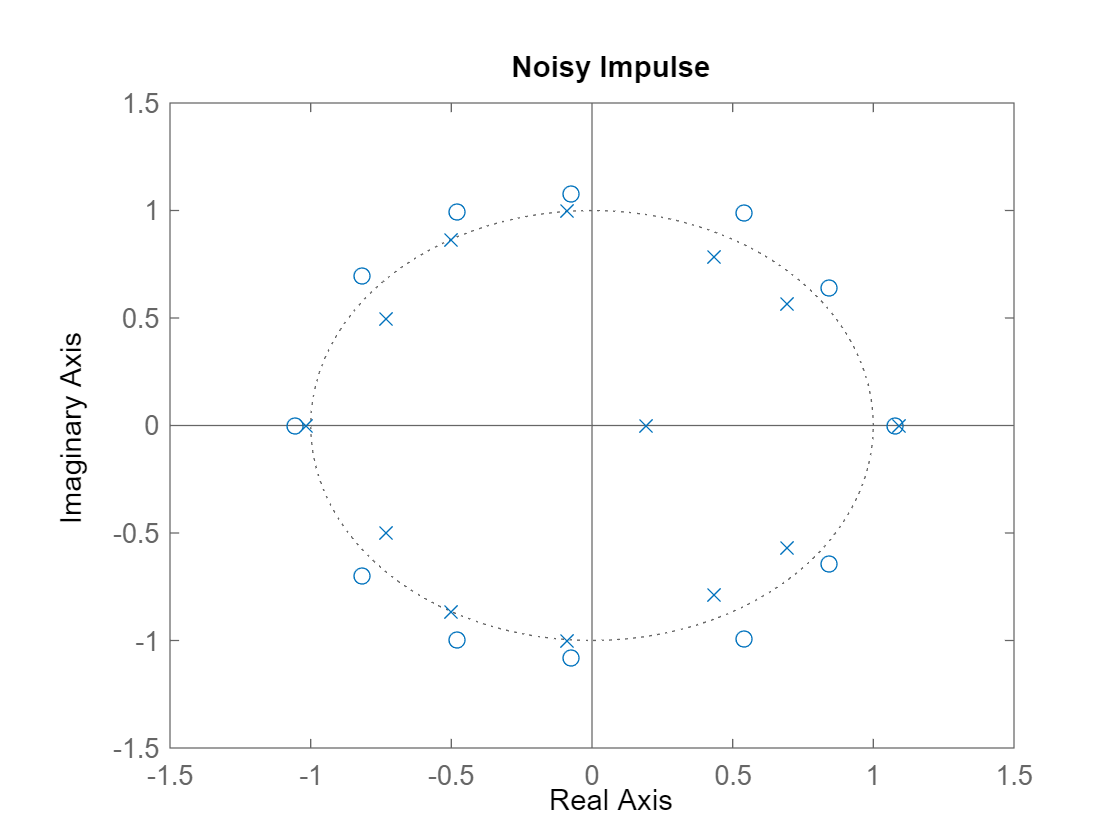

pzmap(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Noisy Impulse")

%Recovered from Optimization
y_afba = [0.665494648785641, 0.022034138651319514, -0.5366663864413213, -0.5258809312683912, -0.04764719330889952, 0.3954914782912253, 0.41385553433712396, 0.059991661873159206, -0.28997349089504026, -0.3244286601563553, -0.06383261810311223, 0.21142693181512767, 0.2533799078008744, 0.06245566863784976, -0.15320970587294008, -0.1971815416873462, -0.05808953354048729, 0.11025928709412536, 0.1529139611911357, 0.05221470640937562, -0.07873003855517996, -0.11818132863495345, -0.045787484078279955, 0.055710719472345155, 0.09103214482785696, 0.03940151131193674, -0.0390052251666344]';
H = y_afba(hankel(1:n,n:end));
r=2;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3908    0.7880
   -0.7880    0.5547


C = Gamma(1,:)

C =    -0.8348   -0.1770


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =    0.4728 + 0.7837i
   0.4728 - 0.7837i


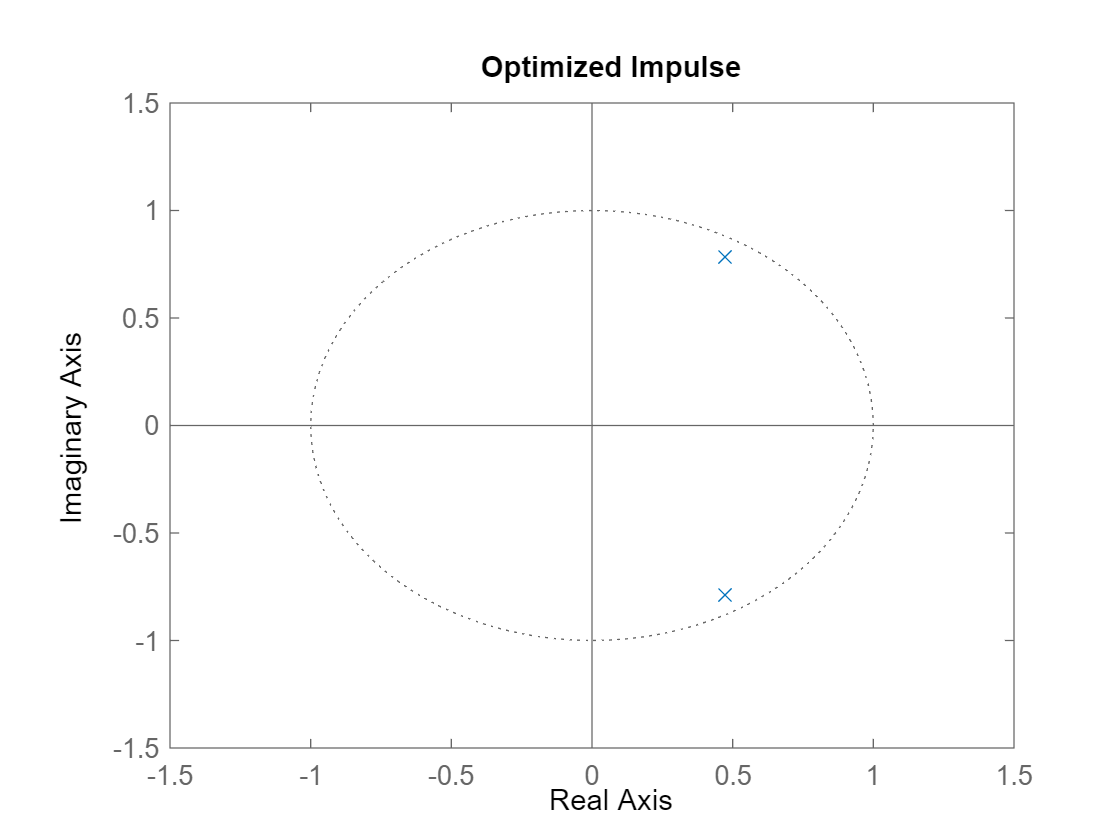

pzplot(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Optimized Impulse")

ss(sys)

ans =
 
  A = 
            x1       x2
   x1     0.45        1
   x2  -0.6075     0.45
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



zero(sys)


ans =

  0×1 empty double column vector



pole(sys)

ans =    0.4500 - 0.7794i
   0.4500 + 0.7794i


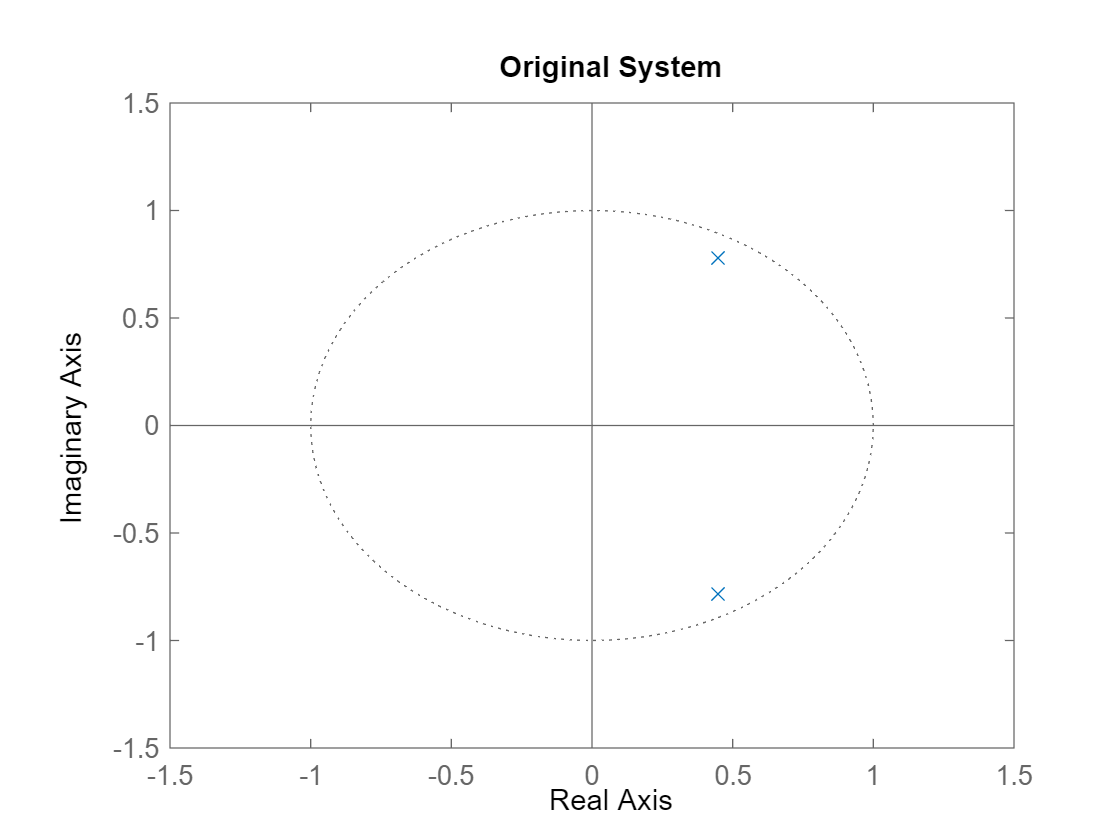

pzplot(sys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Original System")

## NEW PROBLEM

rng(1991)
sys = zpk([],[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i) -0.5*(1-sqrt(2)*i) -0.5*(1+sqrt(2)*i)],1,1);
sspace = ss(sys)

sspace =
 
  A = 
            x1       x2       x3
   x1     -0.5        1        0
   x2     -0.5     -0.5        1
   x3        0        0     0.45
   x4        0        0  -0.6075
 
            x4
   x1        0
   x2        0
   x3        1
   x4     0.45
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



y = impulse(sys,29)

y =          0
         0
         0
         0
    1.0000
   -0.1000
   -0.6500
   -0.0040
   -0.1646
    0.1676


y = y(4:end)

y =          0
    1.0000
   -0.1000
   -0.6500
   -0.0040
   -0.1646
    0.1676
    0.4873
   -0.1347
   -0.2308


sigma = randn(length(y),1)*0.1;
yend = y(1:end)+sigma;
n = (length(yend)+1)/2;
[y, yend, y-yend]

ans =          0    0.0040   -0.0040
    1.0000    0.9130    0.0870
   -0.1000   -0.1154    0.0154
   -0.6500   -0.6833    0.0333
   -0.0040   -0.0414    0.0374
   -0.1646   -0.0508   -0.1138
    0.1676    0.0382    0.1294
    0.4873    0.4006    0.0867
   -0.1347   -0.2350    0.1003
   -0.2308   -0.1397   -0.0910


rank(y(hankel(1:n,n:end)))

ans = 4

svd(y(hankel(1:n,n:end)))'

ans =     1.8456    1.7257    1.0497    0.8957    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


rank(yend(hankel(1:n,n:end)))

ans = 14

svd(yend(hankel(1:n,n:end)))'

ans =     1.7161    1.6568    0.9842    0.9702    0.5901    0.5234    0.5020    0.4348    0.2483    0.2451    0.2291    0.2110    0.1197    0.0622


%Original System's Poles
[0.45*(1-sqrt(3)*i) 0.45*(1+sqrt(3)*i)]'

ans =    0.4500 + 0.7794i
   0.4500 - 0.7794i


%Initial System Determination
H = yend(hankel(1:n,n:end));
r=n;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =     0.3254   -0.7183    0.2813    0.3299   -0.0283    0.0024    0.0628    0.0139    0.0051   -0.0177   -0.0078   -0.0184   -0.0022   -0.0218
    0.7192   -0.2455   -0.2763   -0.4242    0.0442   -0.0172   -0.1024    0.0503   -0.0015    0.0122    0.0130   -0.0179    0.0328   -0.0196
    0.2796    0.2760   -0.4937    0.6683    0.0087    0.1918   -0.0076   -0.0045   -0.0466    0.1021    0.0387    0.2080    0.0585    0.0425
   -0.3295   -0.4255   -0.6708    0.1333   -0.1520   -0.1586    0.0375   -0.0727    0.0414   -0.0905   -0.0354   -0.1504   -0.1185    0.0252
    0.0252    0.0422   -0.0116   -0.1575   -0.6871    0.4835    0.4669   -0.3716   -0.0368    0.0673   -0.0043    0.2156   -0.0447    0.1201
    0.0017    0.0147    0.1874    0.1565   -0.4763   -0.0889   -0.7473   -0.3730   -0.0191    0.0515   -0.0008    0.0834   -0.0062    0.0797
   -0.0636   -0.1051    0.0028    0.0353    0.4748    0.7472   -0.1984   -0.3189    0.0327   -0.0654   -0.0178   -0.0745   -0.1531    0.0839
   -0.010

C = Gamma(1,:)

C =    -0.7088   -0.6556   -0.1359   -0.2251    0.0705    0.1182   -0.1017    0.0823   -0.0436    0.1035    0.0498    0.1595    0.1199   -0.0132


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =    1.1076 + 0.0000i
   0.7218 + 0.5472i
   0.7218 - 0.5472i
   0.4229 + 0.7633i
   0.4229 - 0.7633i
  -0.0674 + 0.9744i
  -0.0674 - 0.9744i
  -0.1583 + 0.0000i
  -0.6267 + 0.7518i
  -0.6267 - 0.7518i


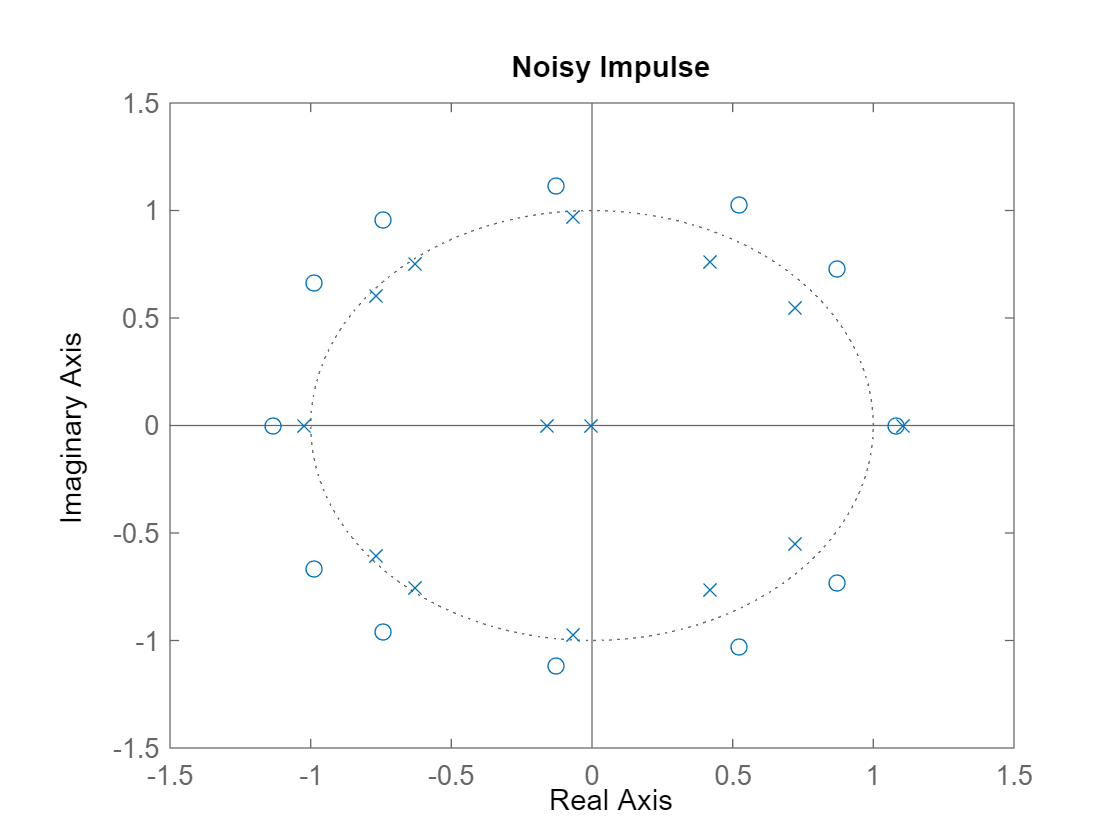

pzmap(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Noisy Impulse")

%Recovered from Optimization
y_afba = [0.031593464796497814, 0.6130263328375509, -0.006480713191293758, -0.38332206048564504, 0.009378859904633288, -0.06375571532114956, 0.09776055889011631, 0.21161179944777056, -0.14036523201587986, -0.0801664307727791, 0.03338011070844618, -0.04213266294921505, 0.08401860375690148, 0.03409103630064907, -0.08101979618197006, 0.01255452935278499, -0.0001047104023862988, -0.01080687756243423, 0.045143733397203956, -0.016204441829472185, -0.02319135109275991, 0.016826120688024984, -0.011149274417427829, 0.005802931664201195, 0.014680493261144142, -0.01639313335036452, 0.000757365584589692]';
H = y_afba(hankel(1:n,n:end));
r=4;
[U,S,V] = svd(H);
U1 = U(:,1:r); U2 = U(:,r+1:end);
Sigma = S(1:r,1:r);
V1 = V(:,1:r); V2 = V(:,r+1:end);
Gamma = (U1*Sigma^0.5);
Delta = (Sigma^0.5*V1');
A = Gamma(1:end-1,:)\Gamma(2:end,:)

A =    -0.3460    0.6828   -0.2895   -0.3427
   -0.6828    0.2957    0.3139    0.3416
    0.2895    0.3139   -0.4963    0.6461
   -0.3427   -0.3416   -0.6461    0.1693


C = Gamma(1,:)

C =     0.5547    0.5708    0.1430    0.0831


newsys = ss(A,[repelem([0],r-1,1);1],C,0,1);
pole(newsys)

ans =   -0.5430 + 0.6942i
  -0.5430 - 0.6942i
   0.3544 + 0.7522i
   0.3544 - 0.7522i


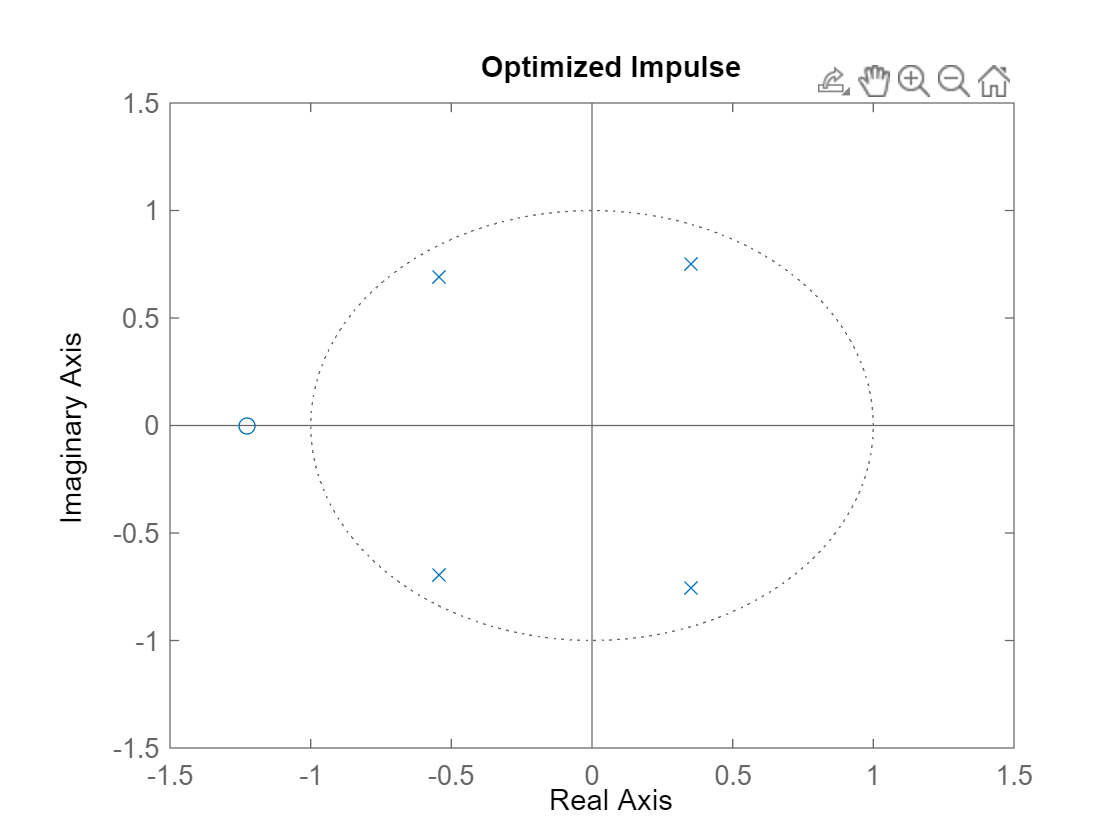

pzplot(newsys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Optimized Impulse")

ss(sys)

ans =
 
  A = 
            x1       x2
   x1     0.45        1
   x2  -0.6075     0.45
 
  B = 
       u1
   x1   0
   x2   1
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 1 seconds
Discrete-time state-space model.



zero(sys)


ans =

  0×1 empty double column vector



pole(sys)

ans =    0.4500 - 0.7794i
   0.4500 + 0.7794i


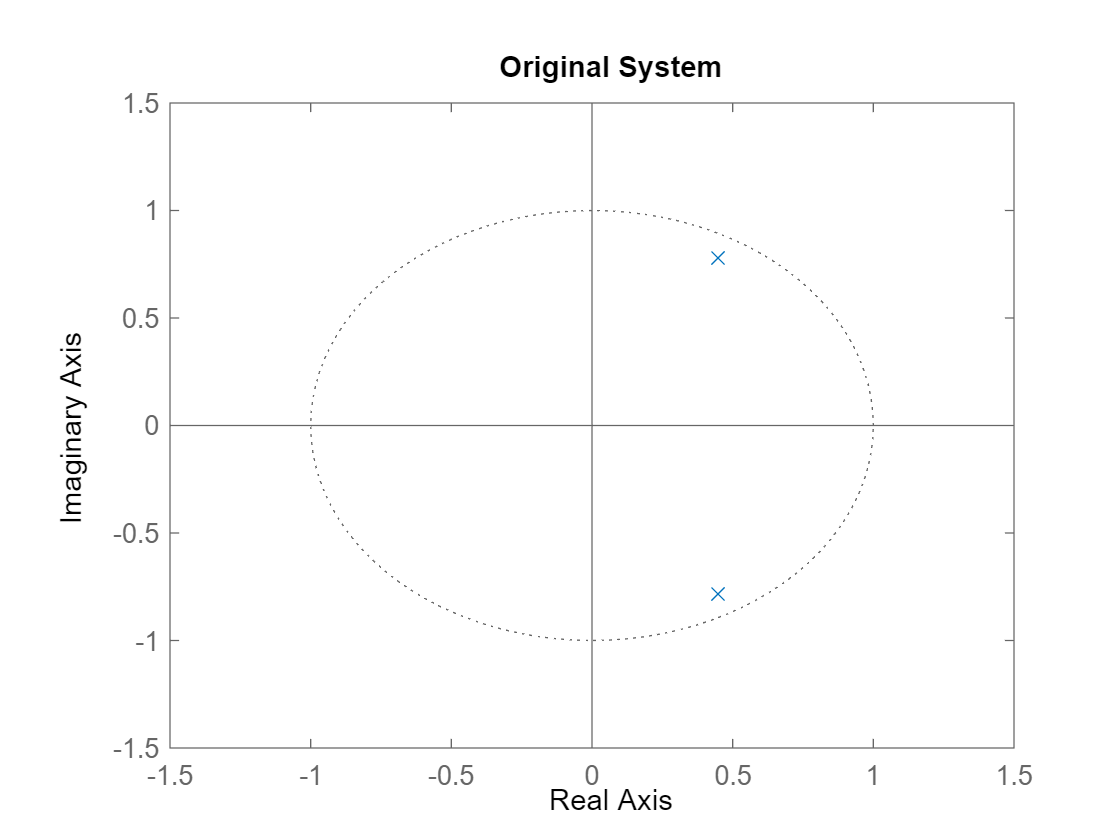

pzplot(sys)
xlim([-1.5,1.5]);ylim([-1.5,1.5]); title("Original System")